## Extract Trace Samples using Map Reduce

Requires the exported service samples of alibaba2020ms.mlx

load('-mat', "../samples_export.mat");
service_samples = export;
clear export;
disp(service_samples);

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Prepare selected columns

We may not care about certain columns, once we fully understand the trace data.

[trace_header, trace_formats, trace_vartypes] = constants();
ignore_columns = ["response_time"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

clear trace_formats;
clear trace_vartypes;
clear ignore_columns;

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

[trace_location, trace_header_lines, ~, ~] = config();
ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);

clear trace_location;
clear trace_header_lines;
clear trace_selected_formats;

prev_ds = copy(ds);
reset(prev_ds);
prev_ds.ReadSize = 10;
read(prev_ds)
clear prev_ds;

### Map Reduce to find valid trace ids

This section filters for valid traces.

To reduce the memory useage the main part of the script is executed once per service. This does take long however it allows intermediate results.

Validation Criteria:

- service_id is a member of our sampled selection

- upstream_ms must be in the list of involved MS or equal "USER"

- downstream_ms must be in the list of involved MS

- The rpc_id parent of every entry of one trace_id is present

- All entries of a trace_id are connected to the "USER" upstream entry

[~, ~, full_traces_dir, ~] = config();
col_idx_trace_id = strcmp(trace_header, "trace_id") > 0;

from_idx = 1;
to_idx = height(service_samples);

% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)trace_reducer(a, b, c, empty_table);

fprintf("*********** Running for services %i to %i ***********\n", from_idx, to_idx);
last_dur = 300.00;
for i=from_idx:to_idx
    time_est = last_dur * ((to_idx + 1) - i);
    fprintf("Estimated Time remaining: %fs\n", time_est);

    tic;
    service_id = service_samples.service_id{i};
    involved_ms = service_samples.involved_ms{i};
    fprintf("*********** (%i/%i) Getting traces for '%s' ***********\n", i, to_idx, service_id);

    % wrap mapper function to pass variable context
    mapFunc = @(a, b, c)trace_mapper(a, b, c, col_idx_trace_id, service_id, involved_ms);
    
    ds_idx = i + 1 - from_idx;
    tmp_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results', 'Display', 'off');

    fprintf("*********** (%i/%i) Creating CSV for '%s' ***********\n", i, to_idx, service_id);
    entries = readall(tmp_ds);
    flatter = vertcat(entries{:,2});
    even_flatter = sortrows(vertcat(flatter{:,1}), "timestamp", "ascend");
    file_name = full_traces_dir + "/traces_" + num2str(i, "%03i") + "_" + service_id + ".csv";
    writetable(even_flatter, file_name, "Delimiter", "\t");
    last_dur = toc;

    clear entries;
    clear flatter;
    clear even_flatter;

    fprintf("*********** (%i/%i) took %fs ***********\n", i, to_idx, last_dur);
end

clear full_traces_dir;
clear col_idx_trace_id;
clear empty_table;
clear mapFunc;
clear reduceFunc;

### Inspect 'all traces'

Naive approach, just reading all data:

% [~, ~, full_traces_dir, ~] = config();
% full_traces_ds = tabularTextDatastore(full_traces_dir, ...
%     "RowDelimiter", "\n", ...
%     "Delimiter", "\t");
% 
% clear full_traces_dir;
% full_traces = readall(full_traces_ds);

### Read 'all traces' and append their service_id+cluster

[~, ~, full_traces_dir, ~] = config();
% Result table
full_traces = table();

% Get file info
files = struct2table(dir(full_traces_dir));
% Get list of files only (no DIRs)
file_name = files.name(files.isdir ~= 1);

tic
for i=1:height(file_name)
    % FOR every file
    f = file_name{i};
    location = full_traces_dir + "/" + f;

    % extract service from filename
    svc = regexp(f, "S_[0-9]+", "match");

    % get cluster with the service name
    clust = service_samples.cluster(service_samples.service_id == svc);

    % read CSV 
    input_table = readall(tabularTextDatastore(location, "RowDelimiter", "\n", "Delimiter", "\t"));

    % append service+cluster to each entry
    service_id = strings(height(input_table),1) + svc;
    cluster = zeros(height(input_table), 1) + clust;
    tmp_table = [input_table table(service_id) table(cluster)];

    % append to all results table
    full_traces = [full_traces; tmp_table];
end
toc

clear full_traces_dir;
clear files;
clear file_name;
clear f;
clear i;
clear location;
clear svc;
clear clust;
clear input_table;
clear service_id;
clear cluster;
clear tmp_table;

ts_minute = floor(single(full_traces.timestamp) / 60000);
full_traces = [full_traces table(ts_minute)];
clear ts_minute;

trace_count_by_group_by_minutes = groupcounts(full_traces,["cluster","ts_minute"]);
cluster_count = max(trace_count_by_group_by_minutes.cluster);

% Calculate grid sizes
plot_count = 8;
cluster_per_figure = ceil(cluster_count / plot_count);
subplot_cols = ceil(sqrt(plot_count));
subplot_rows = ceil(plot_count / subplot_cols);

active_subplot_idx = 0;

% Formatting
ylimits = [0 power(10,4)];

% Create new figure to force the plot into a new popup window
f = figure();
set(f,'Visible','off');
for c=1:cluster_count

    if mod(c, cluster_per_figure) == 1
        % Start a new sub_plot
        active_subplot_idx = active_subplot_idx + 1;
        active_plot = subplot(subplot_rows, subplot_cols, active_subplot_idx);
        hold(active_plot, 'on');
    end

    % Plot into active sub_plot
    data = trace_count_by_group_by_minutes(trace_count_by_group_by_minutes.cluster == c, ["ts_minute", "GroupCount"]);
    label = "C" + num2str(c, "%02i");
    plot(active_plot, data, "ts_minute", "GroupCount", "DisplayName", label);


    if mod(c, cluster_per_figure) == 0
        % Finishing touches to acitve sub_plot
        yscale(active_plot, "log");
        ylim(active_plot, ylimits);
        hold(active_plot, 'off');
        legend(active_plot, 'Location', 'bestoutside');
    end
end
set(f,'Visible','on');

We can spot variety within the traffic per cluster. It does not contain a massive burst or "once in a lifetime" load. Such a workload development could be modeled in future research.

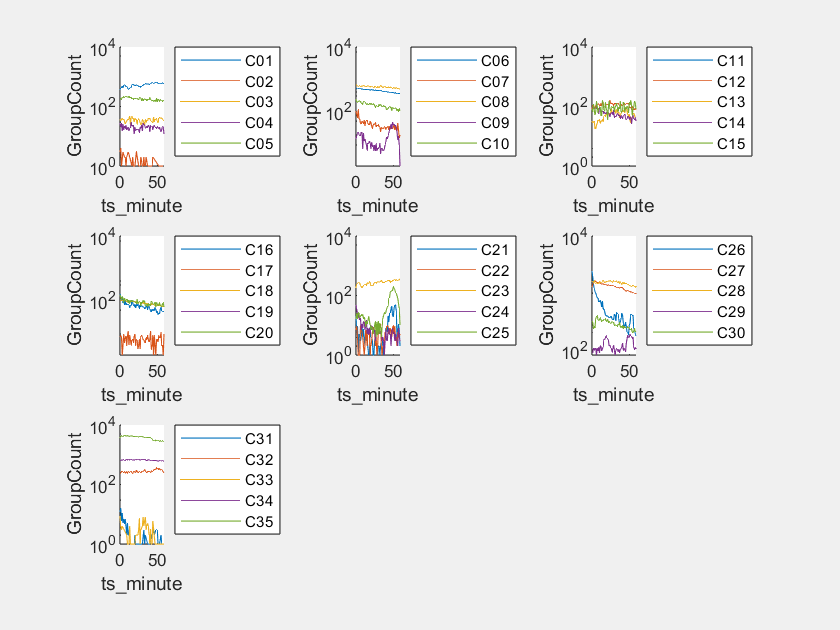


clear data;

clear trace_count_by_group_by_minutes;
clear plot_count;
clear cluster_count;
clear cluster_per_figure;
clear label;
clear active_subplot_idx;
clear active_plot;
clear subplot_cols;
clear subplot_rows;
clear c;
clear ylimits;

histogram(full_traces.timestamp, 60);
title("Trace count over entire time");
ylabel("Trace Count");
xlabel("Timestamp");